## Useful Tips for PS2

### Comparison of principal component 1 and Fiedler vector

The first section shows the relationship between the Fiedler vector of a graph $\mathbf{A}$ and the first eigenvector of the "covariance" matrix $\mathbf{A}_{\text{cov}} = \mathbf{A}^\text{T}\mathbf{A}$.   The first cell loads the data:

load('PS2_data.mat', 'raw_chr15');
load('PS2_data.mat', 'expected_chr15');

% relabel variables for clarity
obs = raw_chr15;
exp = expected_chr15;

% print the dimensionality of the data matrices
size(obs), size(exp)

ans =     82    82


ans =     82    82


I find it helpful to look at the data using the function `imagesc()`, note that matrices are plotted in log-scale to more clearly vizualize large-magnitude differences between high and low-contact regions of the chromosome. Below is the raw matrix of our observations:

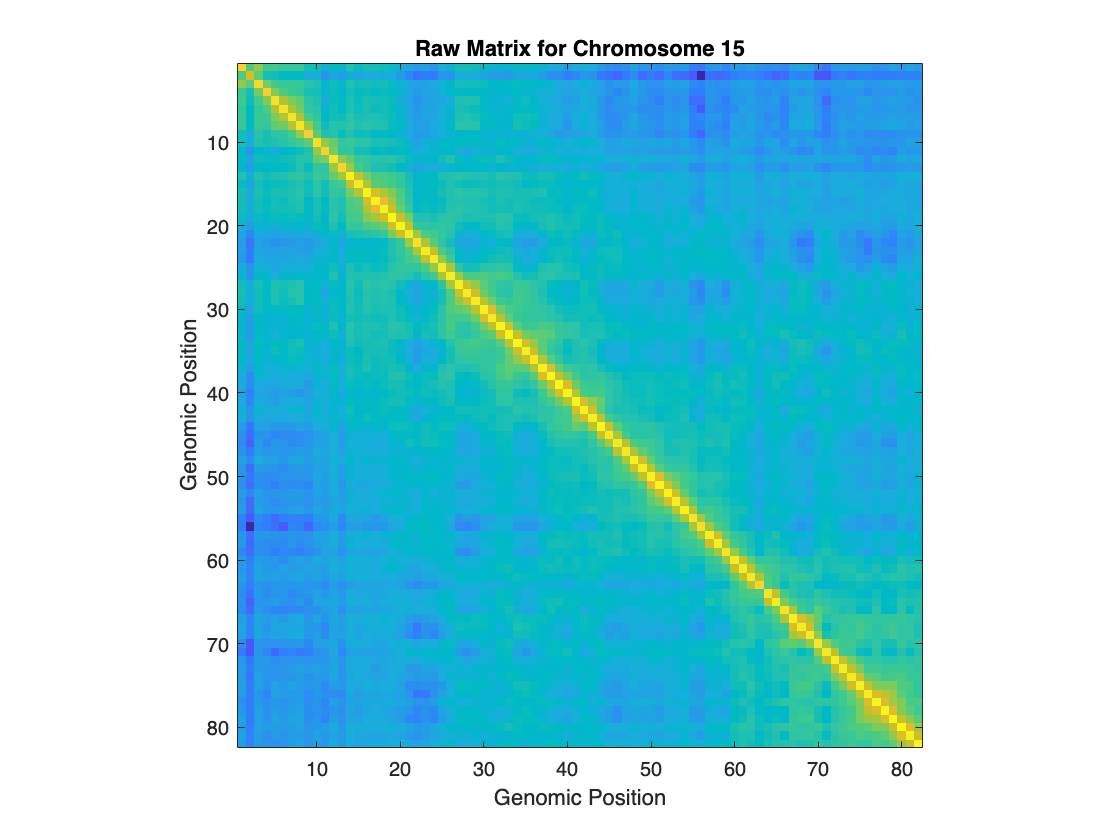

imagesc(log(obs));
xlabel('Genomic Position');
ylabel('Genomic Position');
title('Raw Matrix for Chromosome 15');
axis square;

This plot shows that the expected matrix is just the mean of the diagonal from the observed matrix above. 

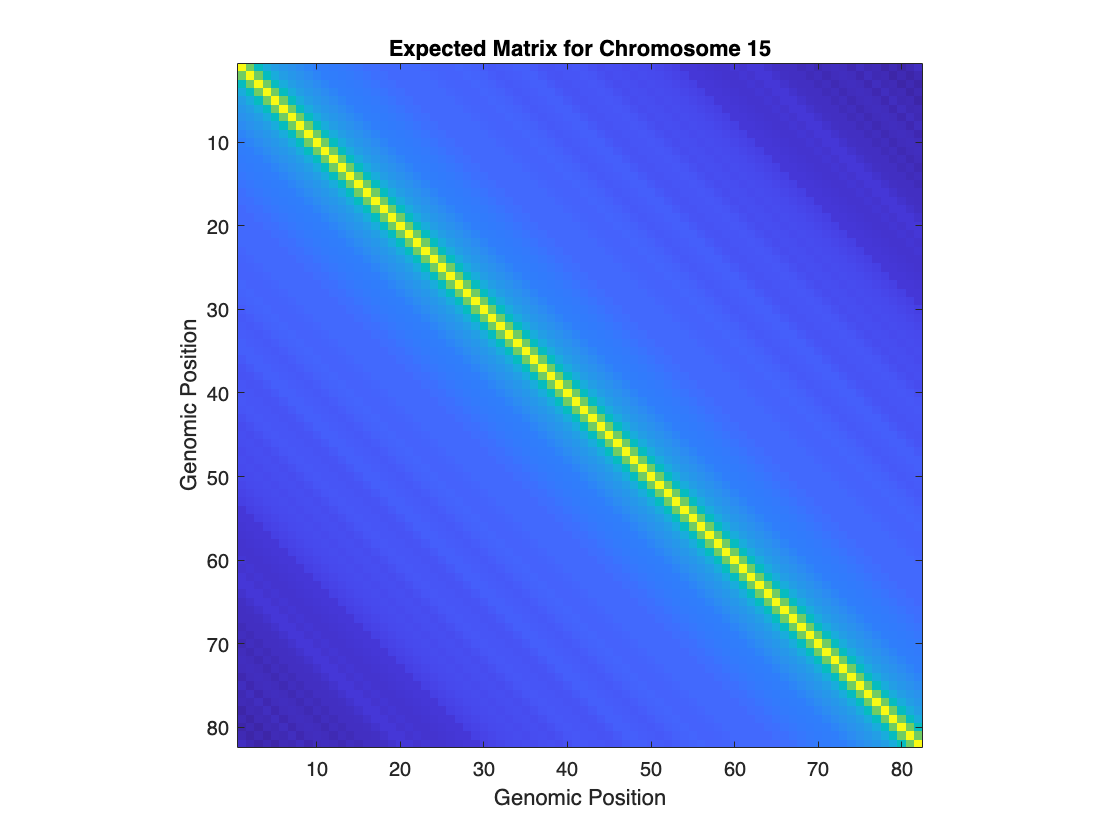

imagesc(log(exp));
xlabel('Genomic Position');
ylabel('Genomic Position');
title('Expected Matrix for Chromosome 15');
axis square;

Construct the normalized adjacency matrix  $\mathbf{A}$ through element-wise division.

A = obs ./ exp;
size(A)

ans =     82    82


Now plot it in log scale:

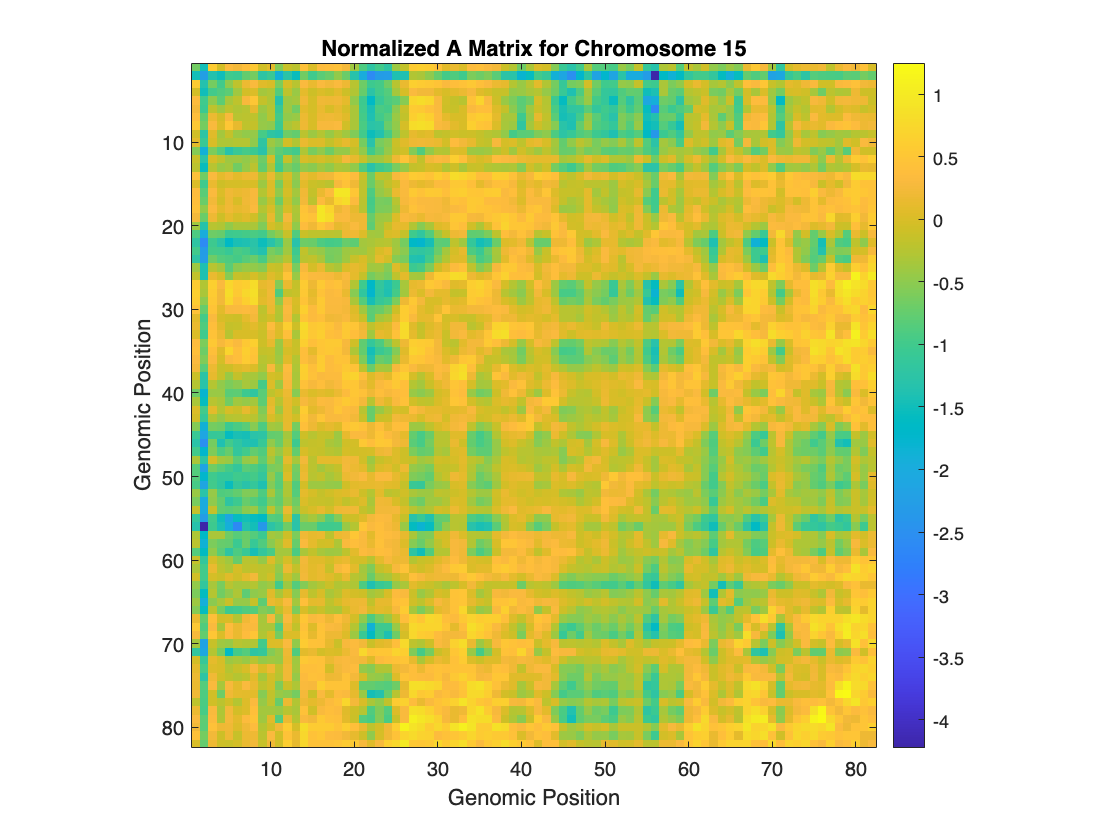

imagesc(log(A));
xlabel('Genomic Position');
ylabel('Genomic Position');
title('Normalized A Matrix for Chromosome 15');
axis square;
colorbar;

Next we compare the Fiedler vector from the normalized Laplacian of $\mathbf{A}$ with the first eigenvector from the matrix $\mathbf{A}^\text{T} \mathbf{A}$. The singular value decomposition of $\mathbf{L}$:

    
$$\mathbf{L} = \mathbf{U \Sigma V^\text{T}}$$


Since the matrix $\mathbf{A}^\text{T} \mathbf{A}$ is symmetric and square the SVD yields the eigenvalues and eigenvectors via:

    
$$\mathbf{A^\text{T} A} = ( \mathbf{U \Sigma V^\text{T}} ) ^ \mathbf{T} ( \mathbf{U \Sigma V^\text{T}} ) =  \mathbf{V \Sigma^2 V^\text{T}}$$


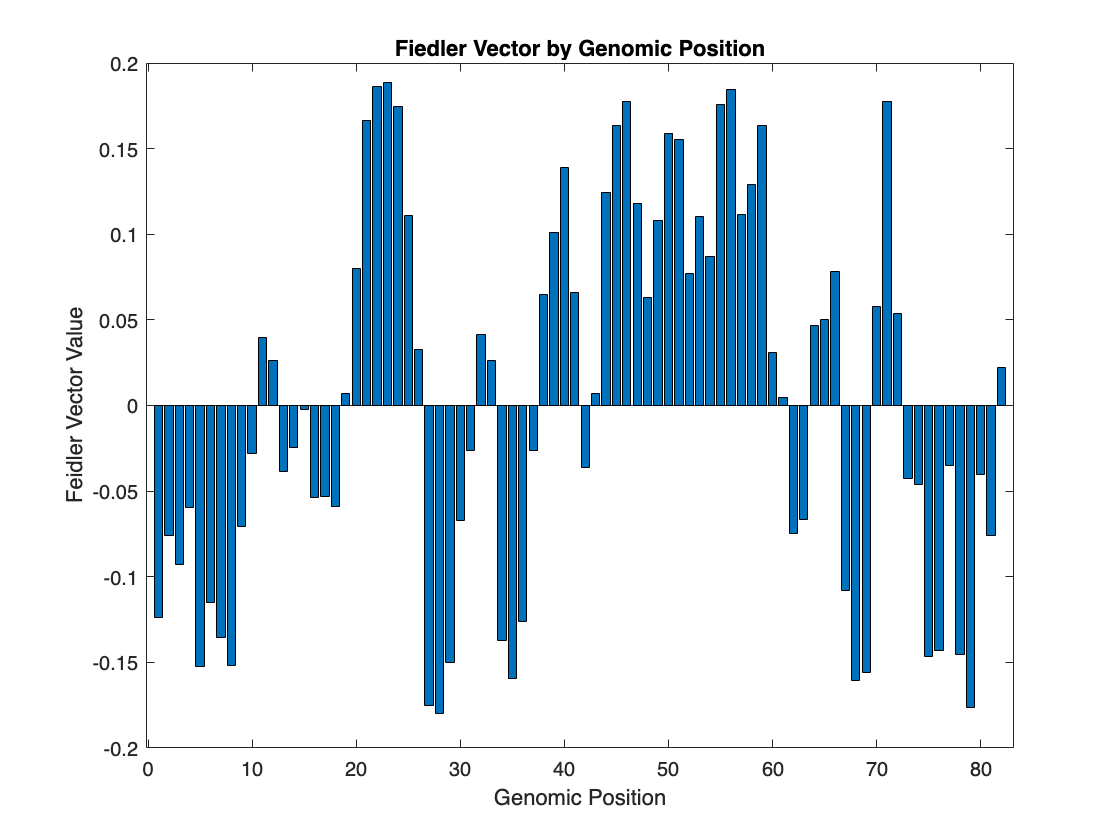

% construct the normalized Laplacian:
D = diag(sum(A));
L = D - A;
S = sqrt(D);
N = S\L/S;

% compute the eigenvalues/eigenvectors of the normalized Laplacian
[u, s, vh] = svd(N); % one can use the `eig()` function here as well, just note that the columns of `u` are ordered differently
svd_eigvalues = diag(s);

% extract the feidler value index (the second-smallest element)
feidler_index = length(svd_eigvalues) - 1;

% extract the column of `u` corresponding to the fiedler number
feidler_vector = u(:,feidler_index);

% plot the fiedler vector
bar(feidler_vector);
xlabel('Genomic Position');
ylabel('Feidler Vector Value');
title('Fiedler Vector by Genomic Position');

Now compare the Feidler vector to the first eigenvector of the "covariance" matrix. 

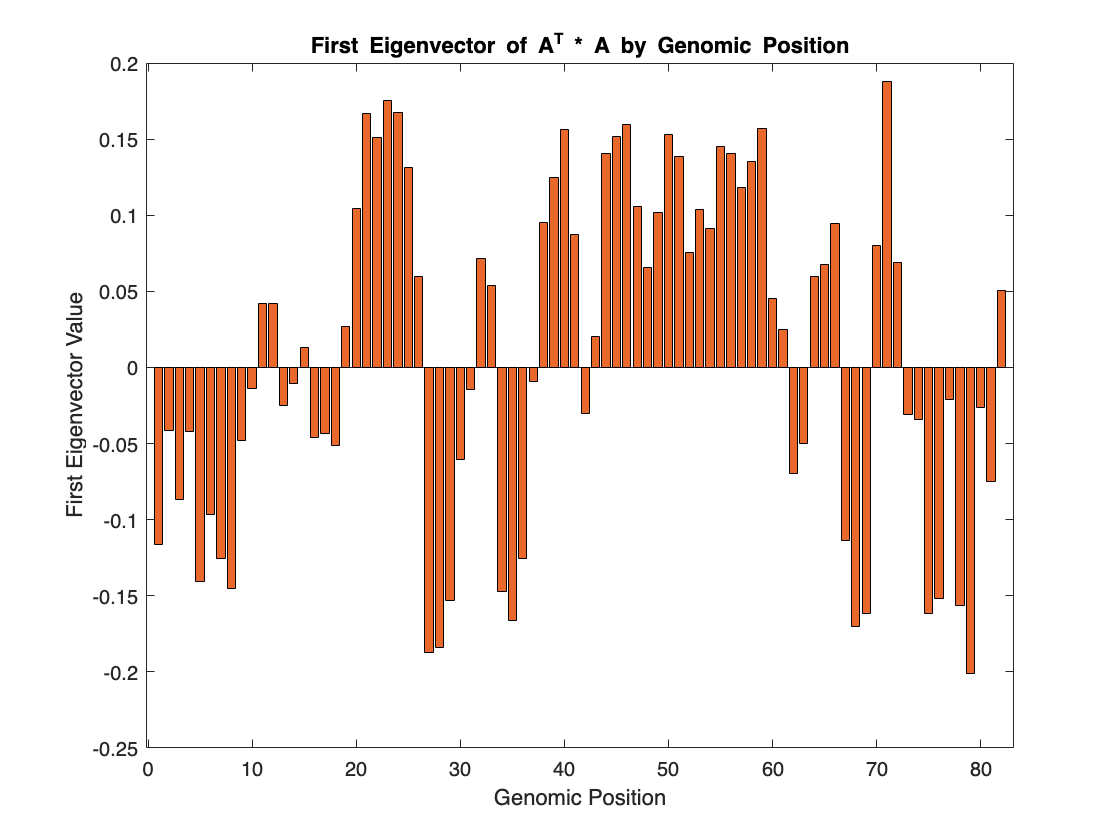

Acov = A'*A;
[u2, s2, vh2] = svd(Acov);

first_eigenvector = u2(:,2);
bar(first_eigenvector, 'FaceColor', [ 0.9100 0.4100 0.1700]);
xlabel('Genomic Position');
ylabel('First Eigenvector Value');
title('First Eigenvector of A^T * A by Genomic Position');

Compare these vectors against one another by plotting both. What do you see?

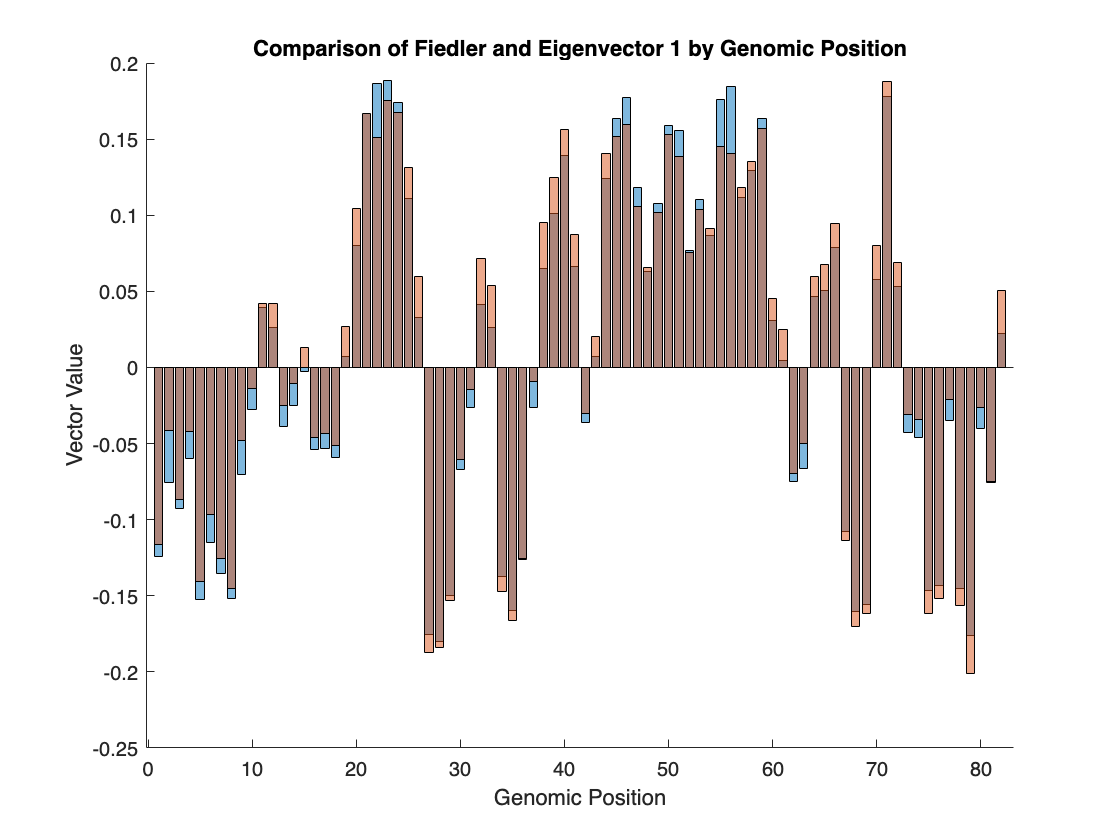

close all;
hold on;
bar(feidler_vector, 'FaceAlpha', 0.5);

xlabel('Genomic Position');
ylabel('Vector Value');

title('Comparison of Fiedler and Eigenvector 1 by Genomic Position');

bar(first_eigenvector, 'FaceAlpha', 0.5);
hold off;

### Data Aggregation Tips

Here, we show a few different ways of working 1D vectors.

load('PS2_data.mat', 'DNASEseq_chr15');
load('PS2_data.mat', 'RNA_15');
load('PS2_data.mat', 'regions_HiC_chr15');
load('PS2_data.mat', 'RNA_columns');

% rename data structures for clarity
dnase = DNASEseq_chr15;
rna = RNA_15;
regions = regions_HiC_chr15;
rna_col = RNA_columns

rna_col = 1×4 cell array
    {'Gene name'}    {'start location'}    {'end location'}    {'expression level'}



size(dnase), size(rna)

ans =         8459           3


ans =    804     4


By looking at the first `n` rows of the object `dnase` we can get a sense for the data. The first column is just the chromosome number. The second column is the index position on chromosome 15 where the DNASE region begins, and the last column is where the DNASE region ends.


nrow = 5;
dnase(1:nrow, :)

ans =           15    21909022    21909265
          15    21926224    21926477
          15    21927246    21927705
          15    22509154    22509398
          15    22514432    22514684


% compute the midpoints. 
% you could also do it like this: `ceil(sum(dnase(:,2:3), 2)./2)`
start = cell2mat(rna(:,2));
end1 = cell2mat(rna(:,3));
rna_region_midpoints = ceil((start + end1)/2);
rna(:, 5) = num2cell(rna_region_midpoints);

nrow = 5;
rna(1:nrow, :)

ans = 5×5 cell array
    {'CHEK2P2' }    {[20487996]}    {[20496811]}    {[      0]}    {[20492404]}
    {'HERC2P3' }    {[20613649]}    {[20711433]}    {[80.4607]}    {[20662541]}
    {'GOLGA6L6'}    {[20737093]}    {[20747114]}    {[ 0.3540]}    {[20742104]}
    {'GOLGA8CP'}    {[20767673]}    {[20781026]}    {[      0]}    {[20774350]}
    {'NBEAP1'  }    {[20874796]}    {[20961480]}    {[ 0.3540]}    {[20918138]}


rna_bin = [ ];  % a data struture to hold the bin number (1 - 82) for each DNASE region

for i = 1:length(rna)
    rna_midpoint = (rna{i, 5}); % this is the midpoint for DNASE region i
    
    bin_number = find(rna_midpoint > regions(1,:) & rna_midpoint < regions(2,:)); % this is an integer between 1 and 82
    
    % handle the DNASE regions whose midpoints are beyond the last bin
    % note that these DNASE events could have been excluded. I keep them
    % because their starting position may be within the bin
    if rna_midpoint > max( regions(2,:))
        bin_number = length(regions(2,:));
    end
    
    % store the bin number (or index of the region column)
    rna_bin(i) = bin_number;
end

% assign the bin numbers back into the dnase data structure
rna(:, 6) = num2cell(rna_bin);
nrow = 10;
rna(1:nrow, :)

ans = 10×6 cell array
    {'CHEK2P2'  }    {[20487996]}    {[20496811]}    {[       0]}    {[20492404]}    {[1]}
    {'HERC2P3'  }    {[20613649]}    {[20711433]}    {[ 80.4607]}    {[20662541]}    {[1]}
    {'GOLGA6L6' }    {[20737093]}    {[20747114]}    {[  0.3540]}    {[20742104]}    {[1]}
    {'GOLGA8CP' }    {[20767673]}    {[20781026]}    {[       0]}    {[20774350]}    {[1]}
    {'NBEAP1'   }    {[20874796]}    {[20961480]}    {[  0.3540]}    {[20918138]}    {[1]}
    {'CT60'     }    {[21145766]}    {[21198633]}    {[       0]}    {[21172200]}    {[2]}
    {'LOC646214'}    {[21932513]}    {[21940739]}    {[399.5743]}    {[21936626]}    {[2]}
    {'CXADRP2'  }    {[22014419]}    {[22016878]}    {[       0]}    {[22015649]}    {[3]}
    {'POTEB'    }    {[22051852]}    {[22083137]}    {[       0]}    {[22067495]}    {[3]}
    {'NF1P2'    }    {[22133180]}    {[22145802]}    {[       0]}    {[22139491]}    {[3]}


T1 = array2table(rna);
T1.Properties.VariableNames = {'gene_name' 'dnase_start' 'dnase_end' 'expression_level' 'dnase_midpoint' 'bin_number'};

T1.gene_name = categorical(T1.gene_name);

T1.dnase_start = cell2mat(T1.dnase_start);
T1.dnase_end = cell2mat(T1.dnase_end);
T1.expression_level = cell2mat(T1.expression_level);
T1.dnase_midpoint = cell2mat(T1.dnase_midpoint);
T1.bin_number = cell2mat(T1.bin_number);
% T1 = array2table(rna);

% look at the first few rows of the new data structure
head(T1)

    gene_name    dnase_start    dnase_end     expression_level    dnase_midpoint    bin_number
    _________    ___________    __________    ________________    ______________    __________

    CHEK2P2      2.0488e+07     2.0497e+07              0           2.0492e+07          1     
    HERC2P3      2.0614e+07     2.0711e+07         80.461           2.0663e+07          1     
    GOLGA6L6     2.0737e+07     2.0747e+07        0.35403           2.0742e+07          1     
    GOLGA8CP     2.0768e+07     2.0781e+07              0           2.0774e+07          1     
    NBEAP1       2.0875e+07     2.0961e+07        0.35403           2.0918e+07          1     
    CT60         2.1146e+07     2.1199e+07              0           2.1172e+07          2     
    LOC646214    2.1933e+07     2.1

% T1.bin_number = str2double(T1.bin_number);

% First, create a function that counts the number of unique elements in an array.
uniqueFunc = @(x) numel(unique(x));

% Next, specify that you want to apply this function to the 'gene_name' column within each 'bin_number' group.
% grpstats() will apply the function to each group and return a table of the results.
rna_per_bin = grpstats(T1, 'bin_number', uniqueFunc, 'DataVars', 'gene_name');

% Finally, display the first few rows of the resulting table.
head(rna_per_bin)

         bin_number    GroupCount    Fun1_gene_name
         __________    __________    ______________

    1        1              5               5      
    2        2              2               2      
    3        3             12              12      
    4        4             14              14      
    5        5              3               3      
    6        6             77              77      
    7        7              5               5      
    8        8              2               2      



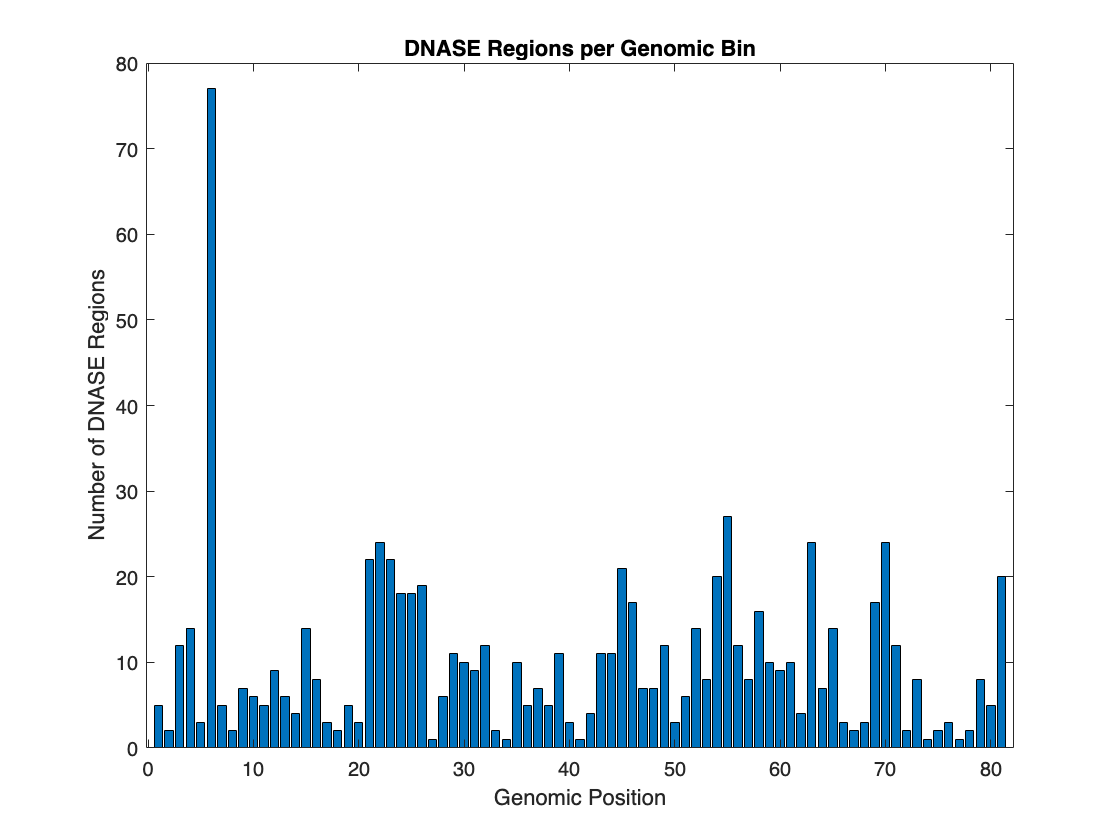

bar(rna_per_bin.GroupCount);

xlabel('Genomic Position');
ylabel('Number of DNASE Regions');
title('DNASE Regions per Genomic Bin');

I compute the midpoint (in genomic coordinates on chromosome 15) of each DNASE region. I assign the vector of midpoints back into the original data stucture. `ceil` is important because the data structure we're aligning to is integer-valued. The fourth column of this matrix is now the single integer coordinate for the DNASE region along the reference genome.

% compute the midpoints. 
% you could also do it like this: `ceil(sum(dnase(:,2:3), 2)./2)`
dnase_region_midpoints = ceil((dnase(:,2)+ dnase(:,3))/2);
dnase(:, 4) = dnase_region_midpoints;

nrow = 5;
dnase(1:nrow, :)

ans =           15    21909022    21909265    21909144
          15    21926224    21926477    21926351
          15    21927246    21927705    21927476
          15    22509154    22509398    22509276
          15    22514432    22514684    22514558


The object `regions` is a 2 row vector with the discrete bins of chromosome 15. Note that there are 82 bins, the same number as the dimensionality of the Hi-C matrix.

size(regions)

ans =      2    82


For simplicity, we'll loop through the `dnase` regions and find the bin that the center of the DNASE region falls into. Note, when we do it this way we see that a number of DNASE events fall outside the genomic coordinates. Since we've chosen midpoints, we add all these elements to the last bin.

dnase_bin = [ ];  % a data struture to hold the bin number (1 - 82) for each DNASE region

for i = 1:length(dnase)
    dnase_midpoint = dnase(i, 4); % this is the midpoint for DNASE region i
    bin_number = find(dnase_midpoint > regions(1,:) & dnase_midpoint < regions(2,:)); % this is an integer between 1 and 82
    
    % handle the DNASE regions whose midpoints are beyond the last bin
    % note that these DNASE events could have been excluded. I keep them
    % because their starting position may be within the bin
    if dnase_midpoint > max( regions(2,:))
        bin_number = length(regions(2,:));
    end
    
    % store the bin number (or index of the region column)
    dnase_bin(i) = bin_number;
end

% assign the bin numbers back into the dnase data structure
dnase(:, 5) = dnase_bin;
nrow = 5;
dnase(1:nrow, :)

ans =           15    21909022    21909265    21909144           2
          15    21926224    21926477    21926351           2
          15    21927246    21927705    21927476           2
          15    22509154    22509398    22509276           3
          15    22514432    22514684    22514558           3


Using this, we can count the number of detected DNASE regions in each bin using `grpstats`. But first we convert it to a table object and name the columns. This makes working with somethings a little easier:

% create a table
T = array2table(dnase);

% modify variable names
T.Properties.VariableNames = {'chromosome' 'dnase_start' 'dnase_end' 'dnase_midpoint' 'bin_number'};

% look at the first few rows of the new data structure
head(T)

    chromosome    dnase_start    dnase_end     dnase_midpoint    bin_number
    __________    ___________    __________    ______________    __________

        15        2.1909e+07     2.1909e+07      2.1909e+07          2     
        15        2.1926e+07     2.1926e+07      2.1926e+07          2     
        15        2.1927e+07     2.1928e+07      2.1927e+07          2     
        15        2.2509e+07     2.2509e+07      2.2509e+07          3     
        15        2.2514e+07     2.2515e+07      2.2515e+07          3     
        15        2.2798e+07     2.2798e+07      2.2798e+07          3     
        15        2.2833e+07     2.2834e+07      2.2834e+07          3     
        15        2.2837e+07     2.2837e+07      2.2837e+07          3     



Now we can count the DNASE regions per bin easily. Check out the documentation on [grpstats()](https://www.mathworks.com/help/stats/grpstats.html).

dnase_per_bin = grpstats(T,'bin_number', 'numel', 'DataVars', {'chromosome'});
head(dnase_per_bin)

         bin_number    GroupCount    numel_chromosome
         __________    __________    ________________

    2        2              3                3       
    3        3             25               25       
    4        4             22               22       
    5        5              1                1       
    6        6             50               50       
    7        7             66               66       
    8        8             12               12       
    9        9             24               24       



Plot directly from the table.

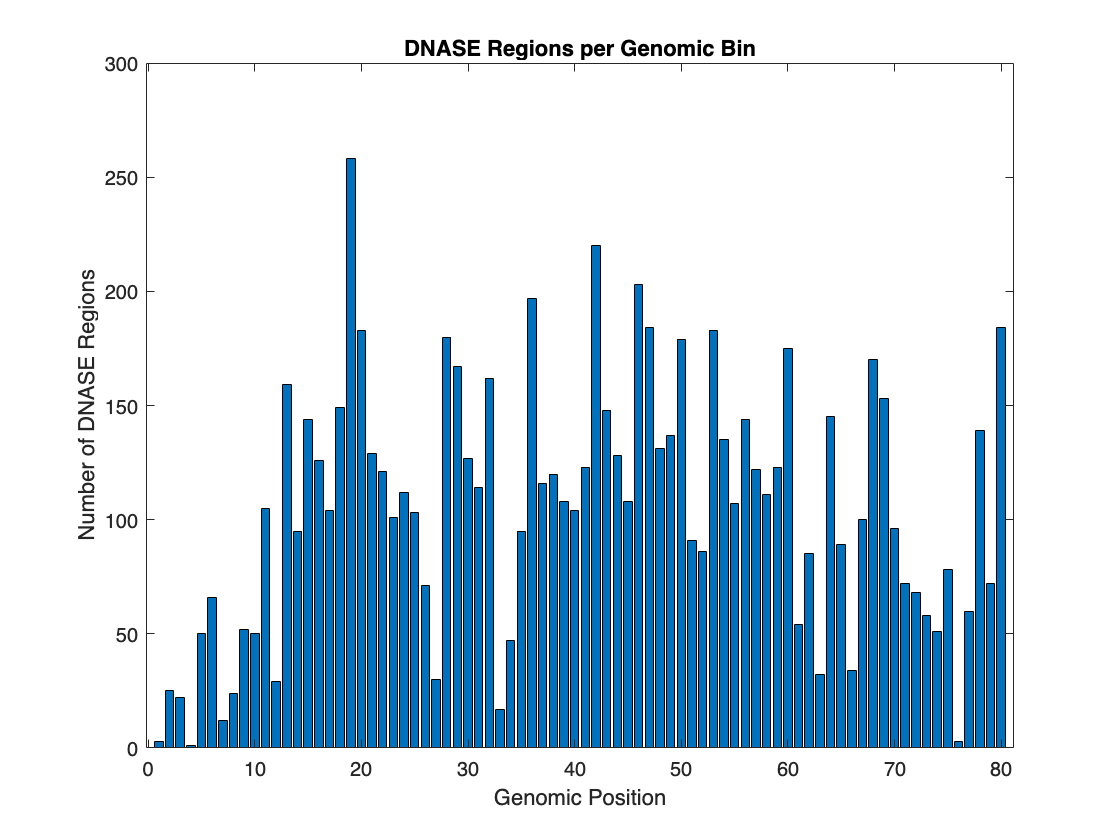

bar(dnase_per_bin.GroupCount);

xlabel('Genomic Position');
ylabel('Number of DNASE Regions');
title('DNASE Regions per Genomic Bin');